# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves firm's investment problem.

%}

## Model: Model of Firm Investment.

The representative firm is infinitely lived. It maximizes the present value of its lifetime profit by choosing capital investment subject to a convex cost of adjustment. The dynamic programming problem associated with this is:


$$V(A,K,p) = \underset{i}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{i}{K}\right)^2K - pi + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ ,$$



$$K' = (1-\delta)K + i  \ , $$


where $p$ is the price of investment, $|\rho|<1$ and $\epsilon'\sim\mathcal{N}(0,\sigma^2)$. Substituting the law of motion gives


$$V(A,K,p) = \underset{K'}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{K' - (1-\delta)K}{K}\right)^2K - p(K' - (1-\delta)K) + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ .$$


## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\Inclass3_Code\Convex Adjustment\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\Inclass3_Code\Convex Adjustment\Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function iteration.

We will solve the model using value function iteration. Our guess is that firm value is zero over the state space.


$$V(A,K) = 0 \ .$$


### Solve, Simulate & Plot 1a

Calls: solve1.m, simulate1.m and my_graph1.m.

Simulate a single firm over time.

t = cputime;
sol1 = solve1.firm_problem(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.

Converged in 401 iterations.

------------End of Value Function Iteration.------------


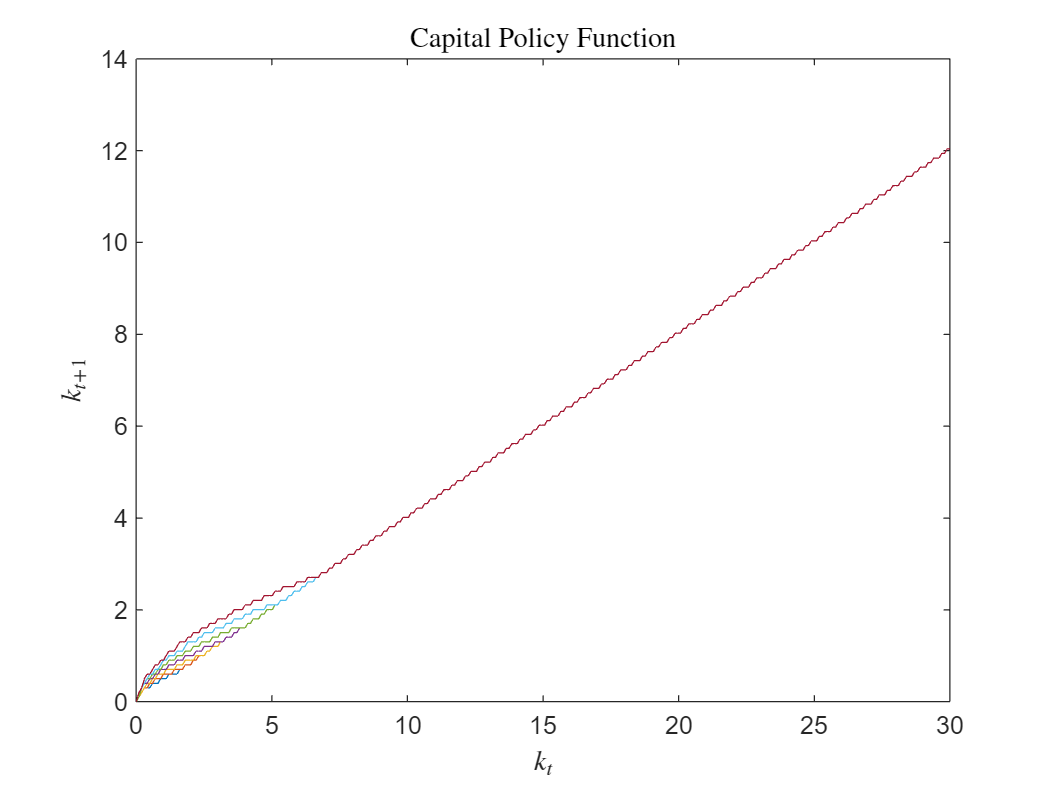

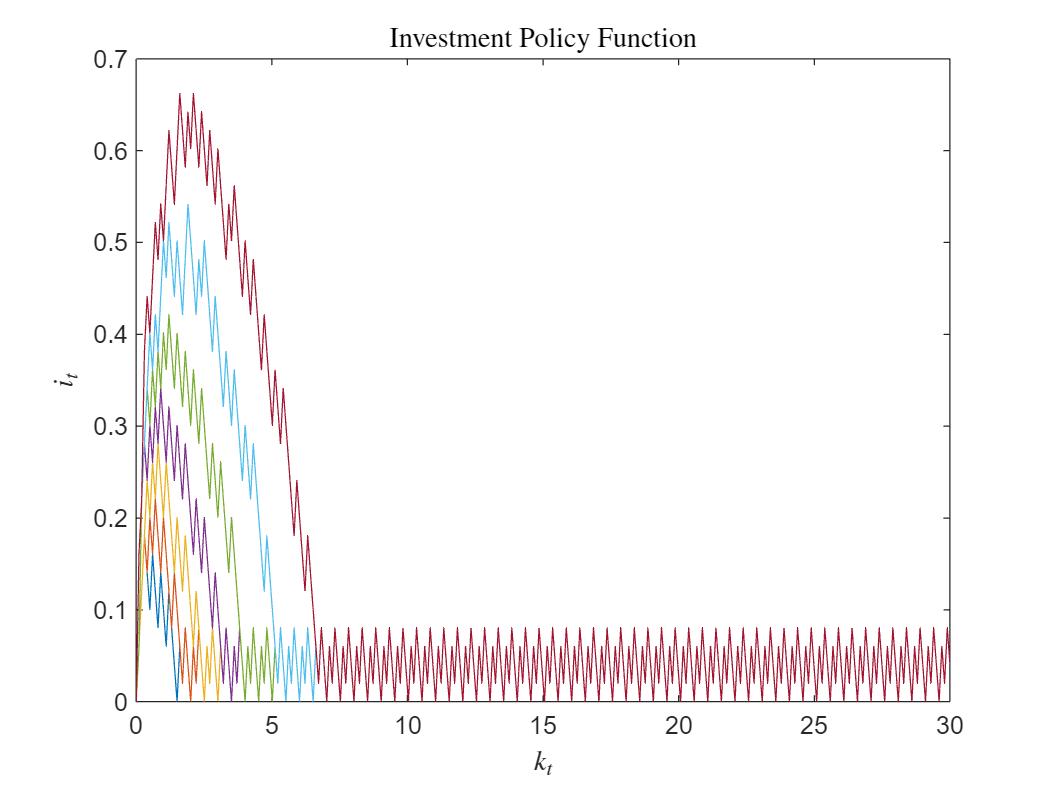

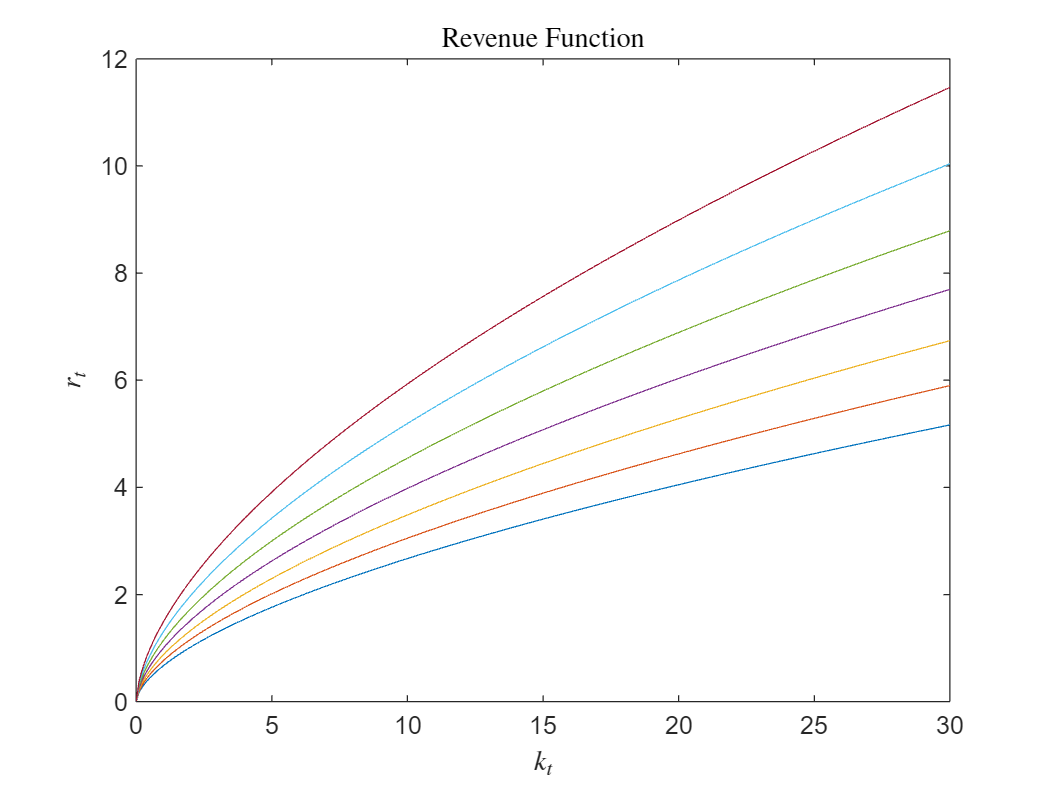

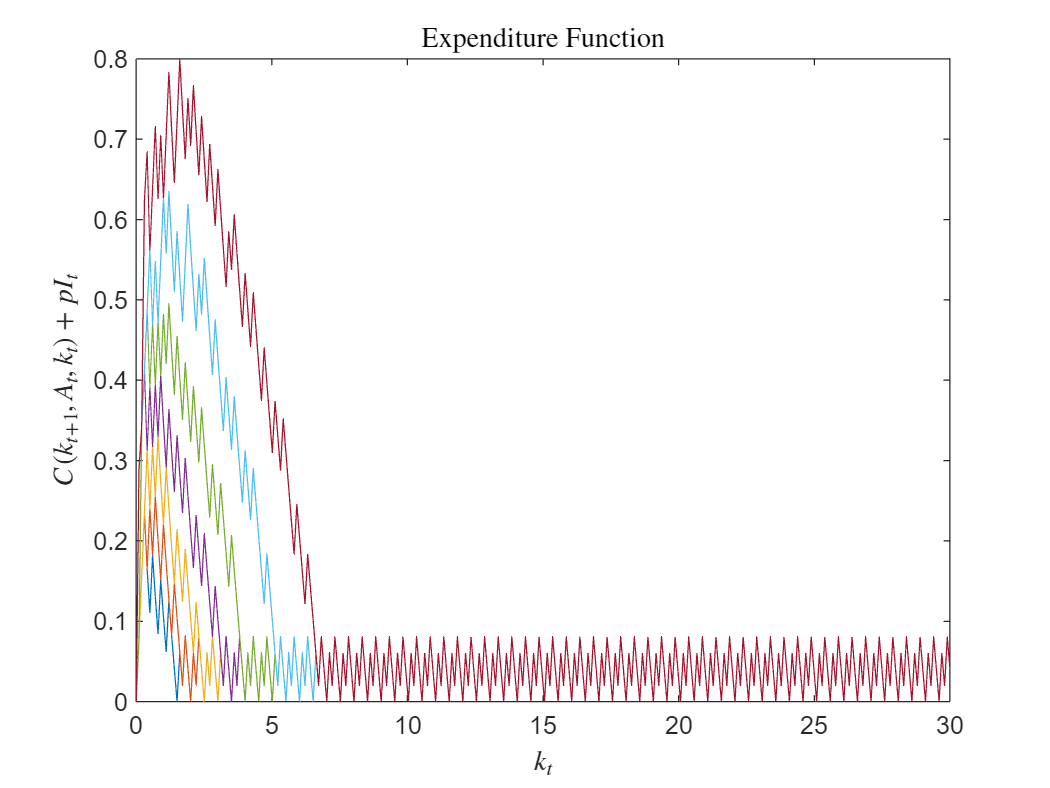

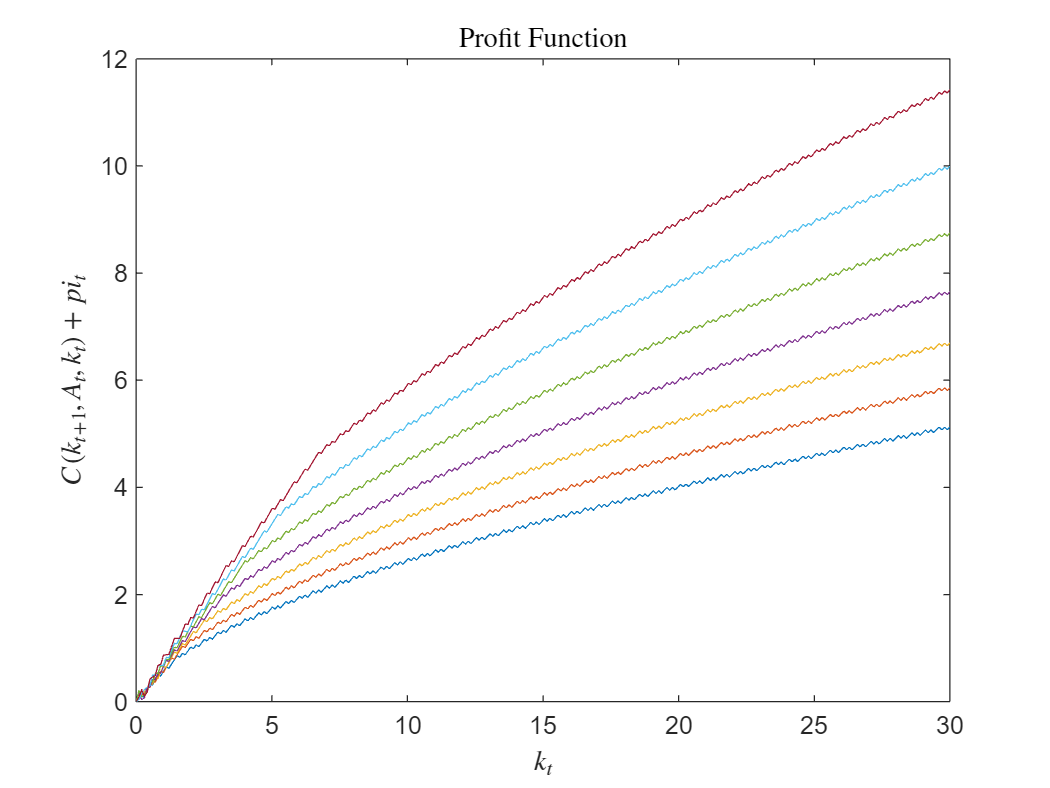

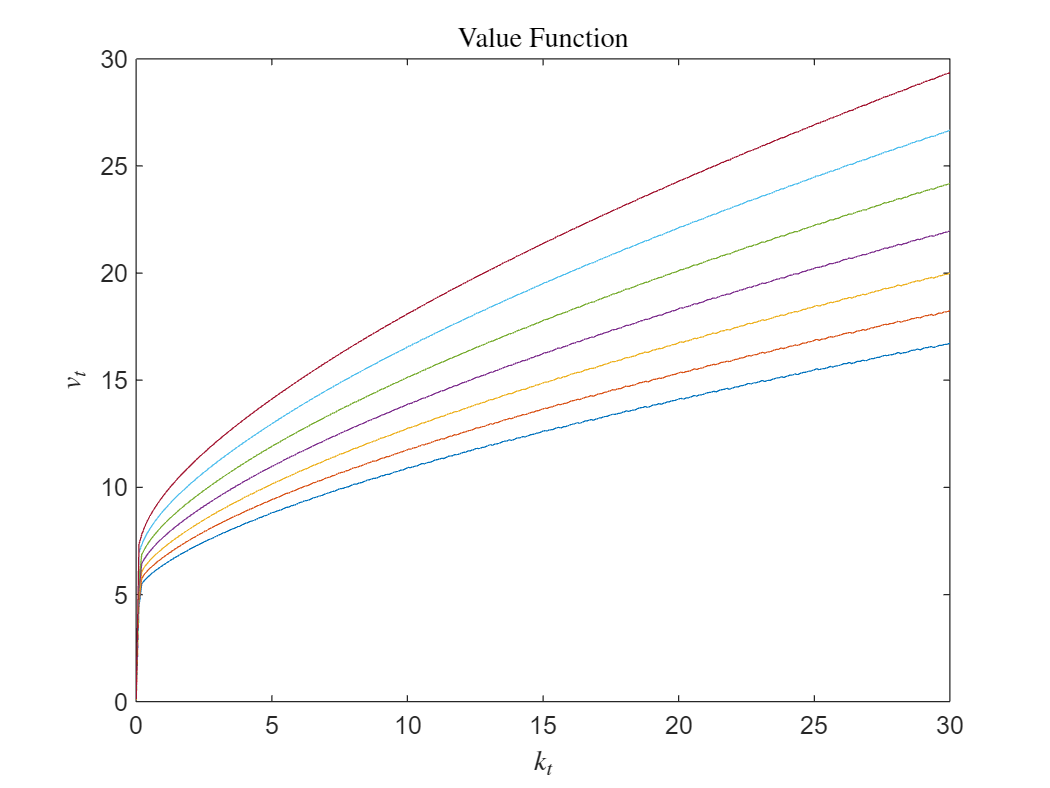

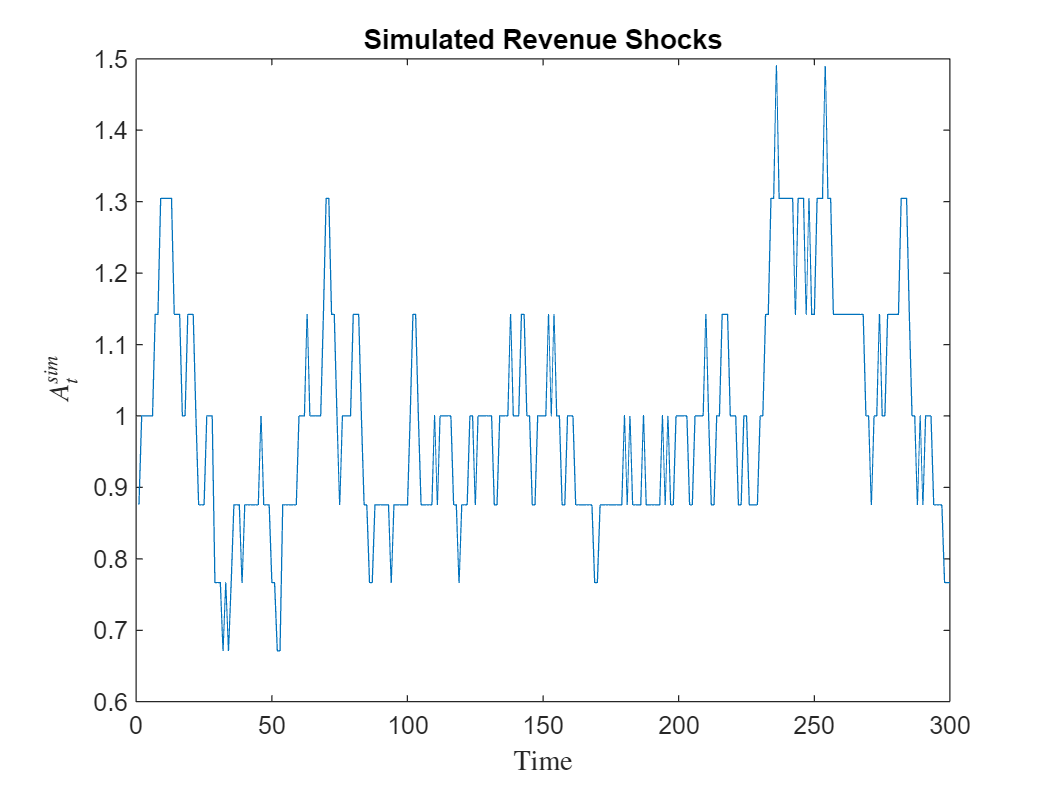

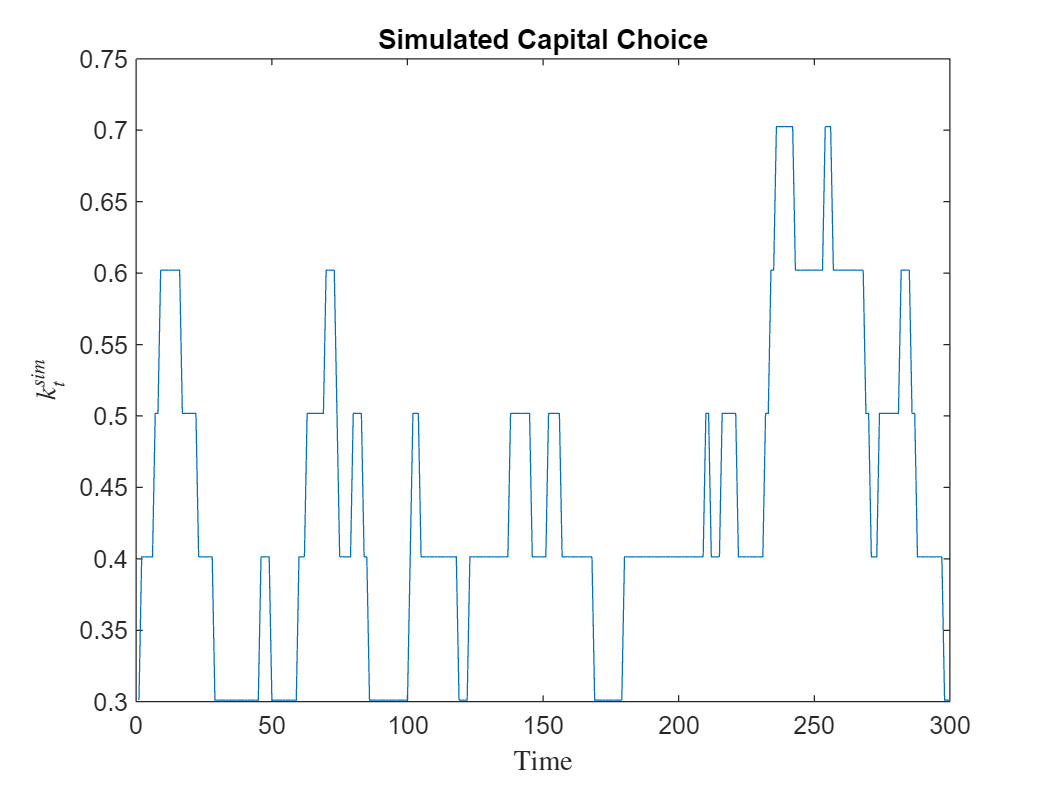

sim1 = simulate1.firm_dynamics(par,sol1); % Simulate the model.
my_graph1.plot_policy(par,sol1,sim1) % Plot the model functions and time series.

fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 10.2188 seconds.


### Solve, Simulate & Plot 1b

Calls: solve2.m, simulate2.m and my_graph2.m.

Simulate a panel of firms over time.

t = cputime;
sol2 = solve2.firm_problem(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.

Converged in 401 iterations.

------------End of Value Function Iteration.------------


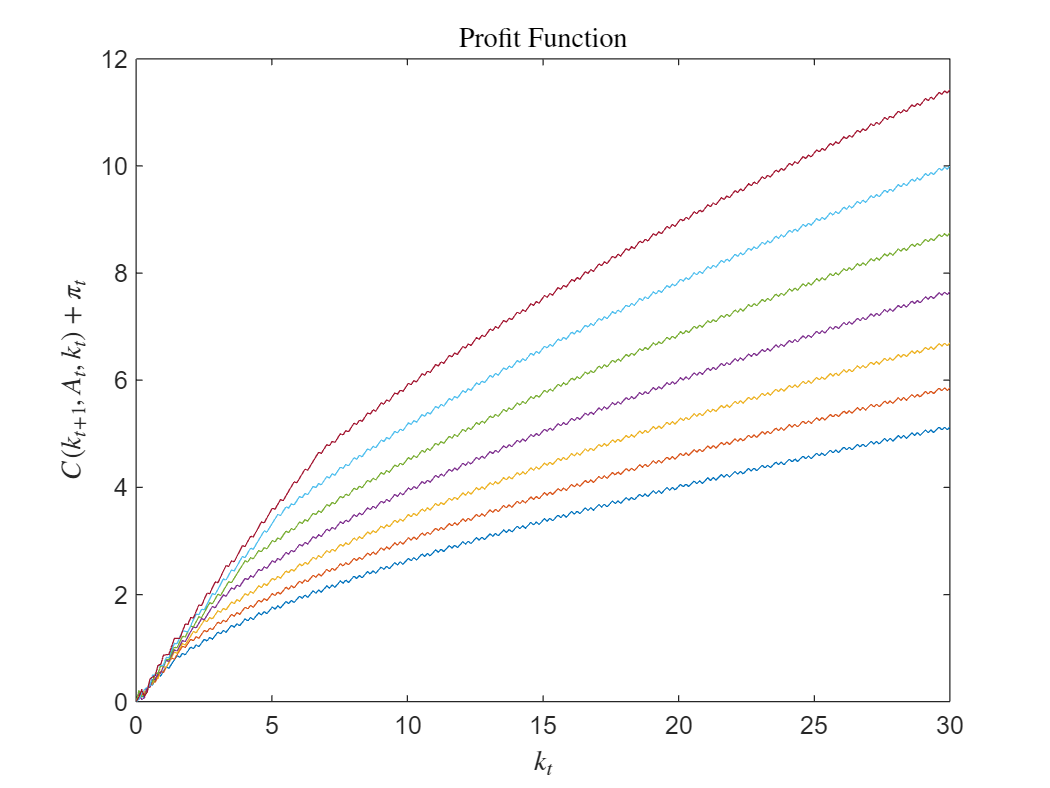

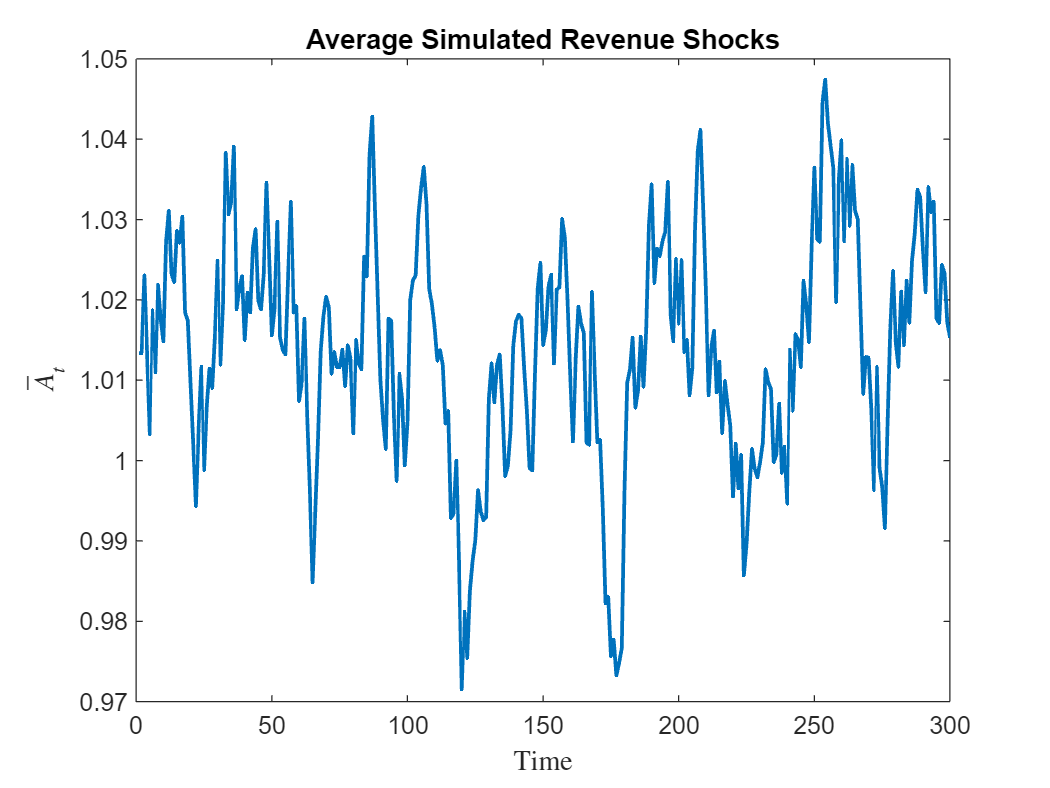

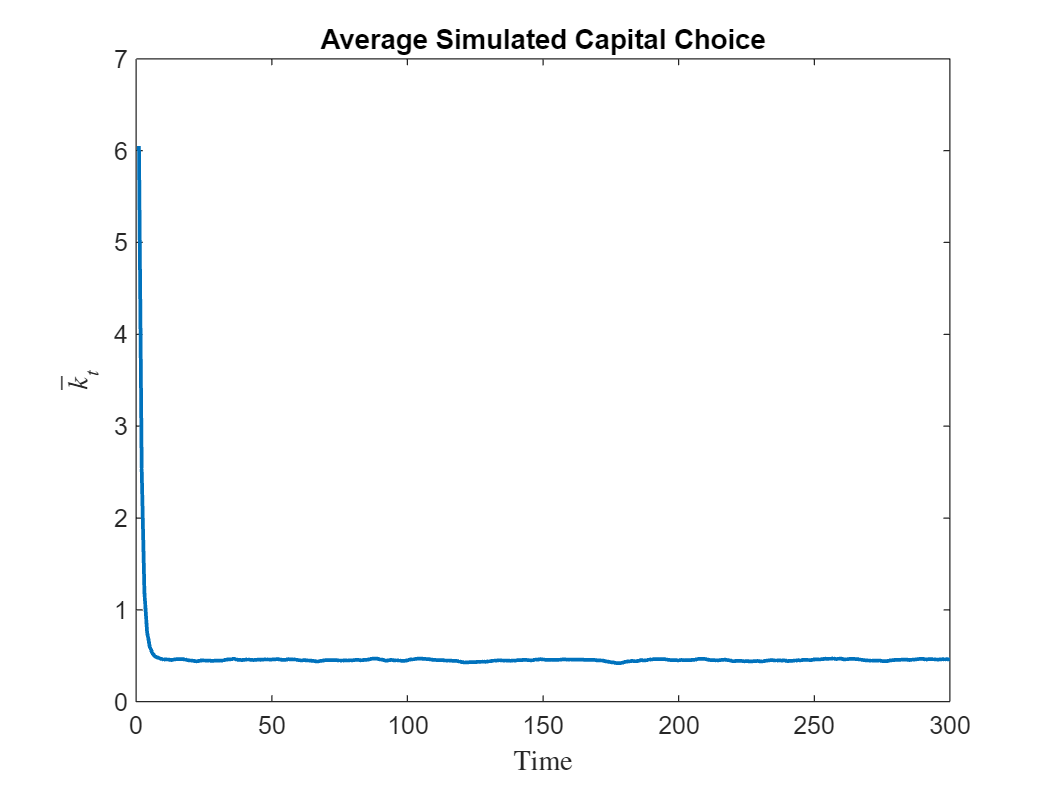

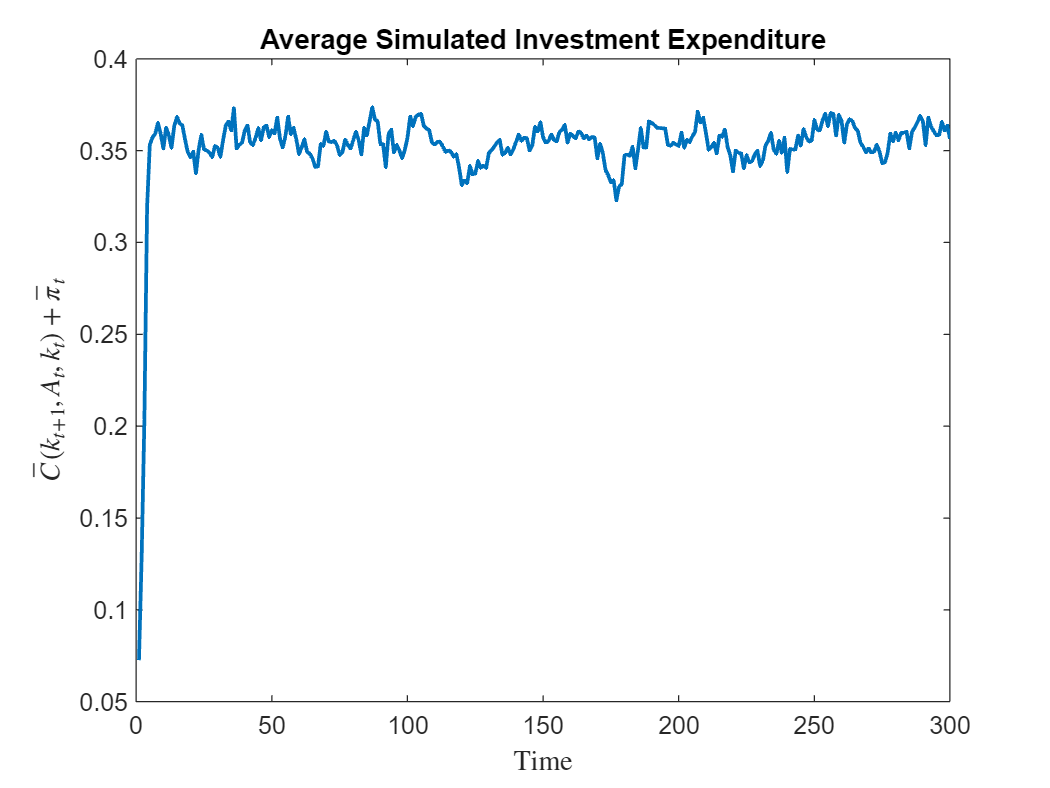

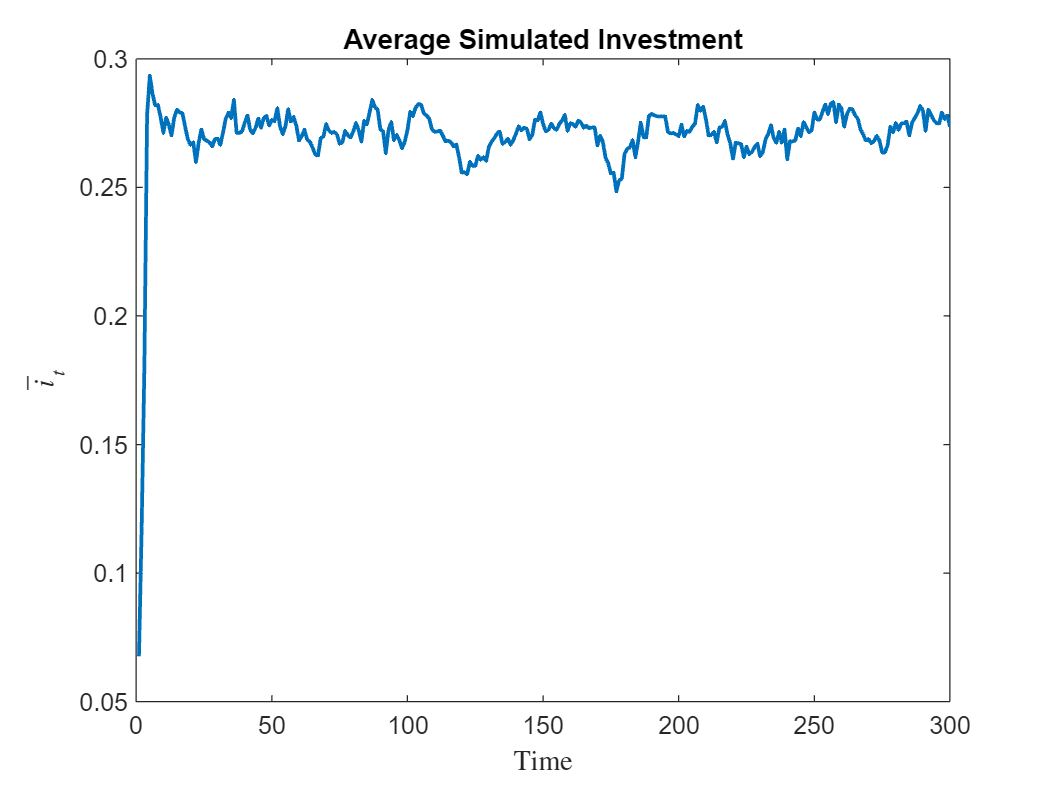

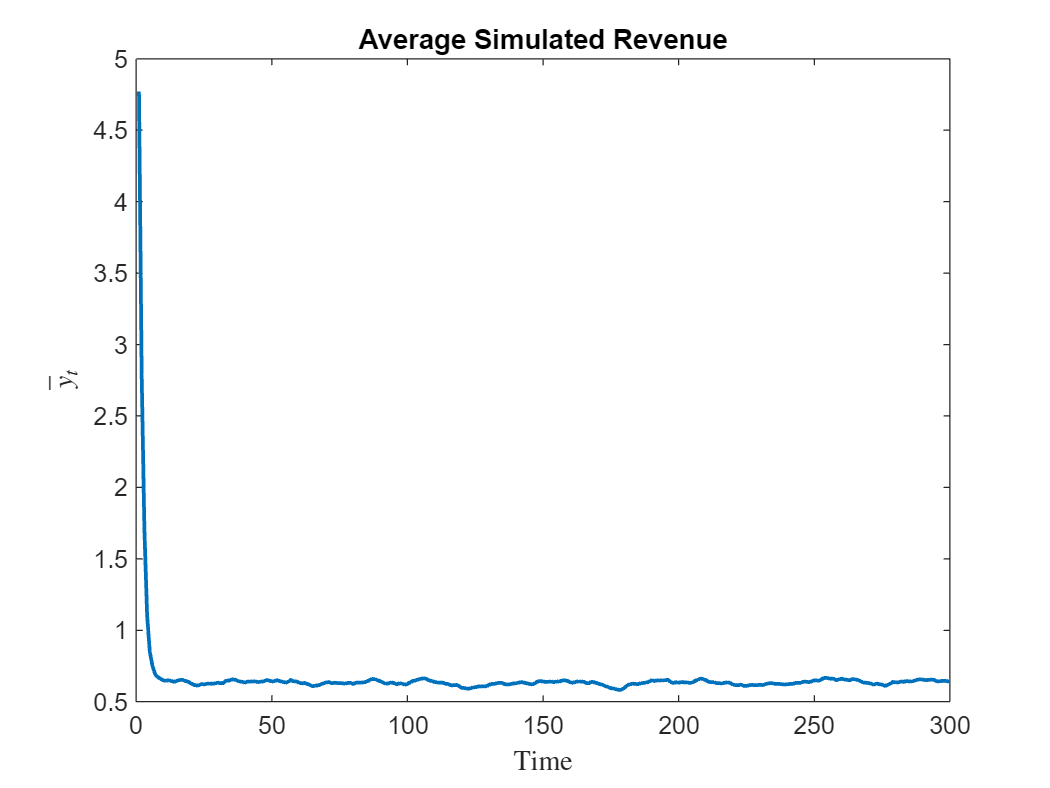

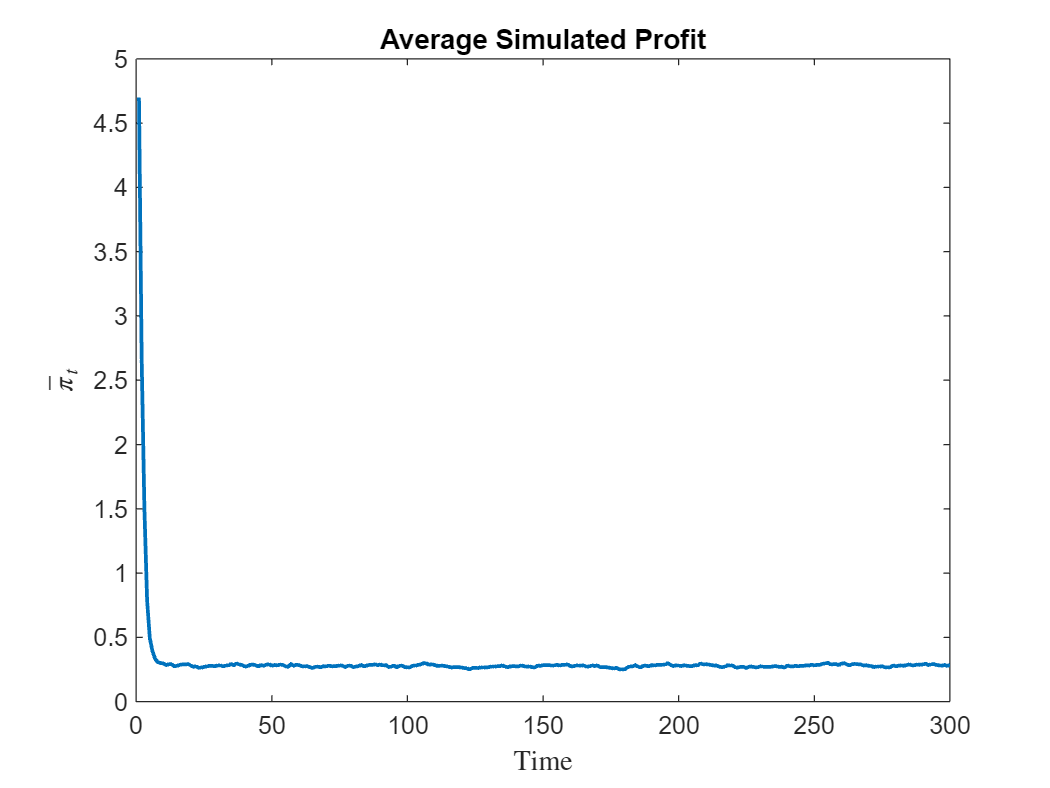

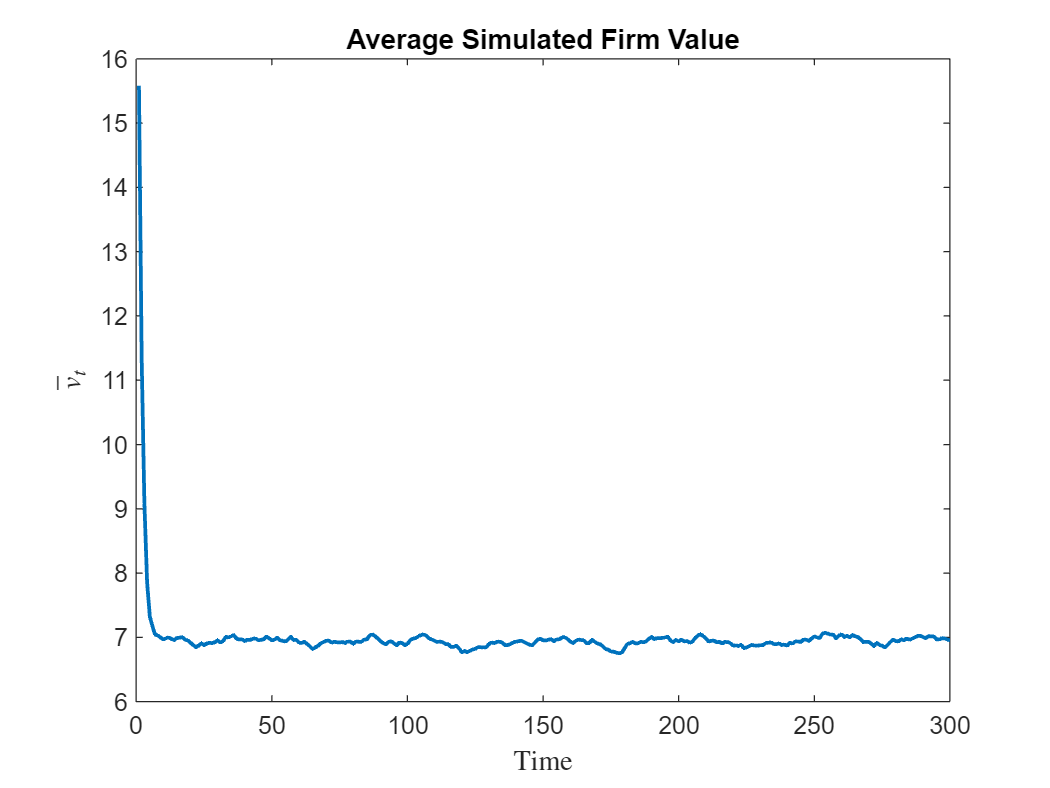

sim2 = simulate2.firm_dynamics(par,sol2); % Simulate the model.
my_graph2.plot_policy(par,sol2,sim2) % Plot the model functions and time series.

## Set the parameters and generate the state space.

Calls: model2.m.

The grid for assets is set exogenously.

par = model2.setup; % Set parameters.
par = model2.gen_grids(par); % Generate the state space.

### Solve, Simulate & Plot 1c

Calls: solve3.m, simulate3.m and my_graph3.m.

Simulate a single firm over time.

t = cputime;
sol3 = solve3.firm_problem(par); % Solve the model using Value Function Iteration.

------------ Beginning Value Function Iteration ------------

Iteration: 25, Diff: 2.905239
Iteration: 50, Diff: 1.044409
Iteration: 75, Diff: 0.376411
Iteration: 100, Diff: 0.135657
Iteration: 125, Diff: 0.048890
Iteration: 150, Diff: 0.017620
Iteration: 175, Diff: 0.006350
Iteration: 200, Diff: 0.002289
Iteration: 225, Diff: 0.000825
Iteration: 250, Diff: 0.000297
Iteration: 275, Diff: 0.000107
Iteration: 300, Diff: 0.000039
Iteration: 325, Diff: 0.000014
Iteration: 350, Diff: 0.000005
Iteration: 375, Diff: 0.000002

Converged in 390 iterations with diff = 0.000001.

------------ End of Value Function Iteration ------------


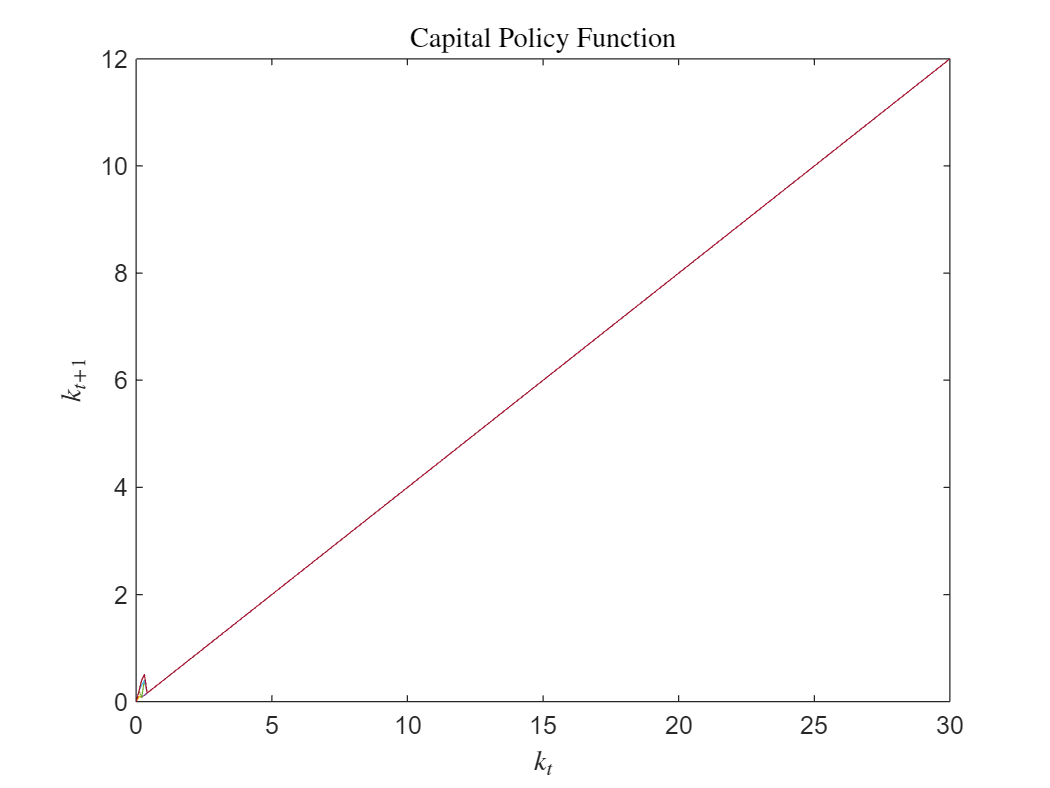

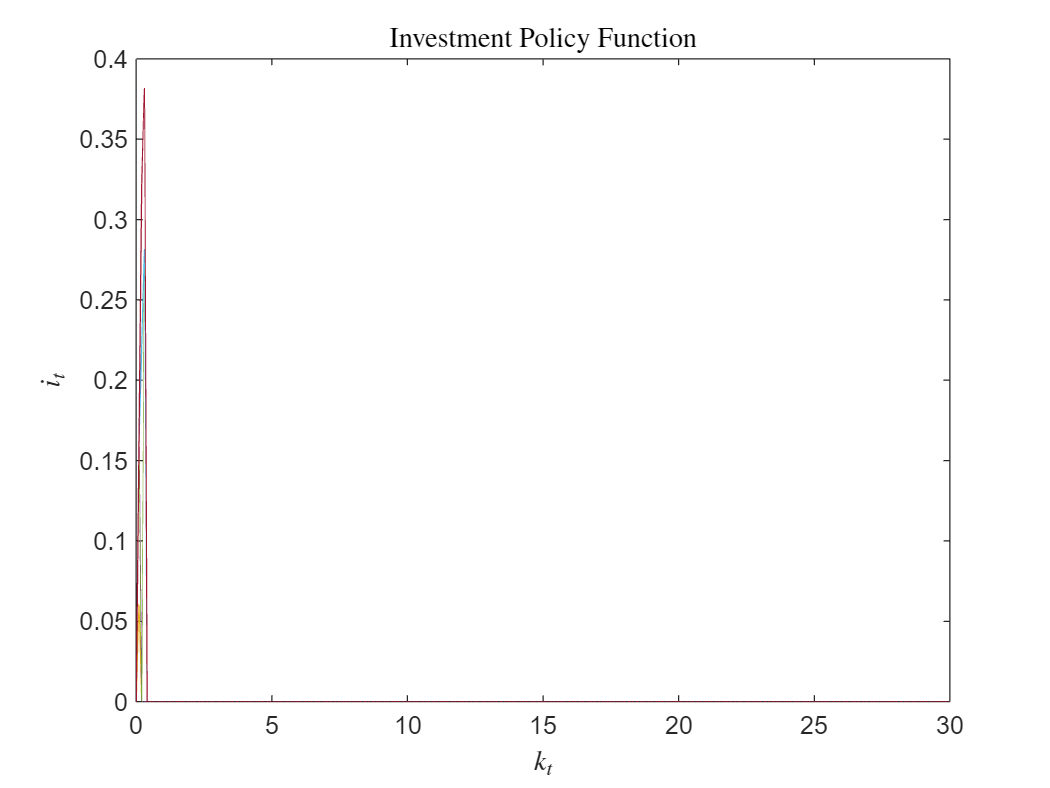

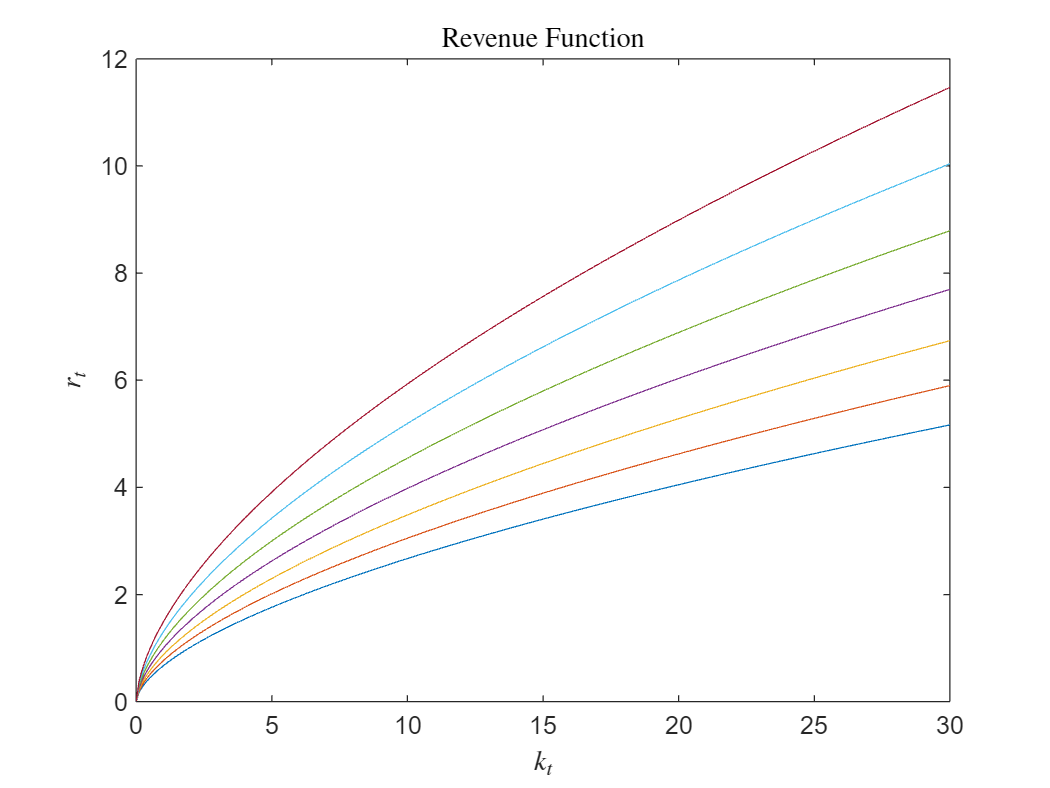

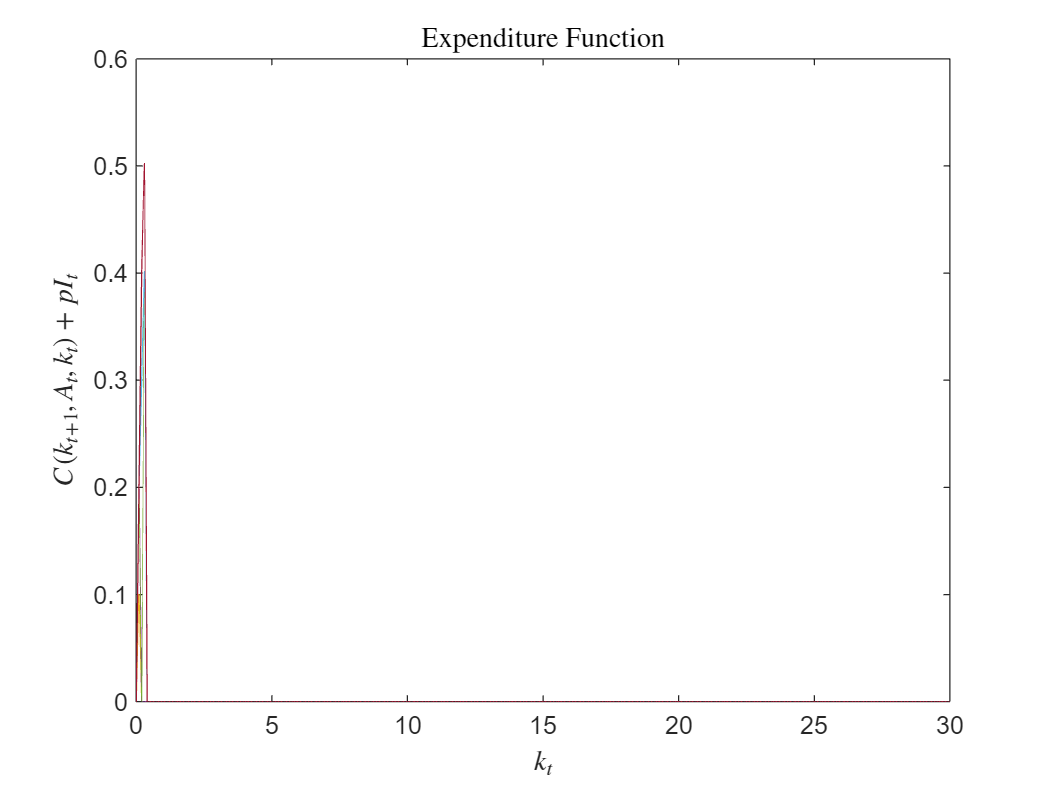

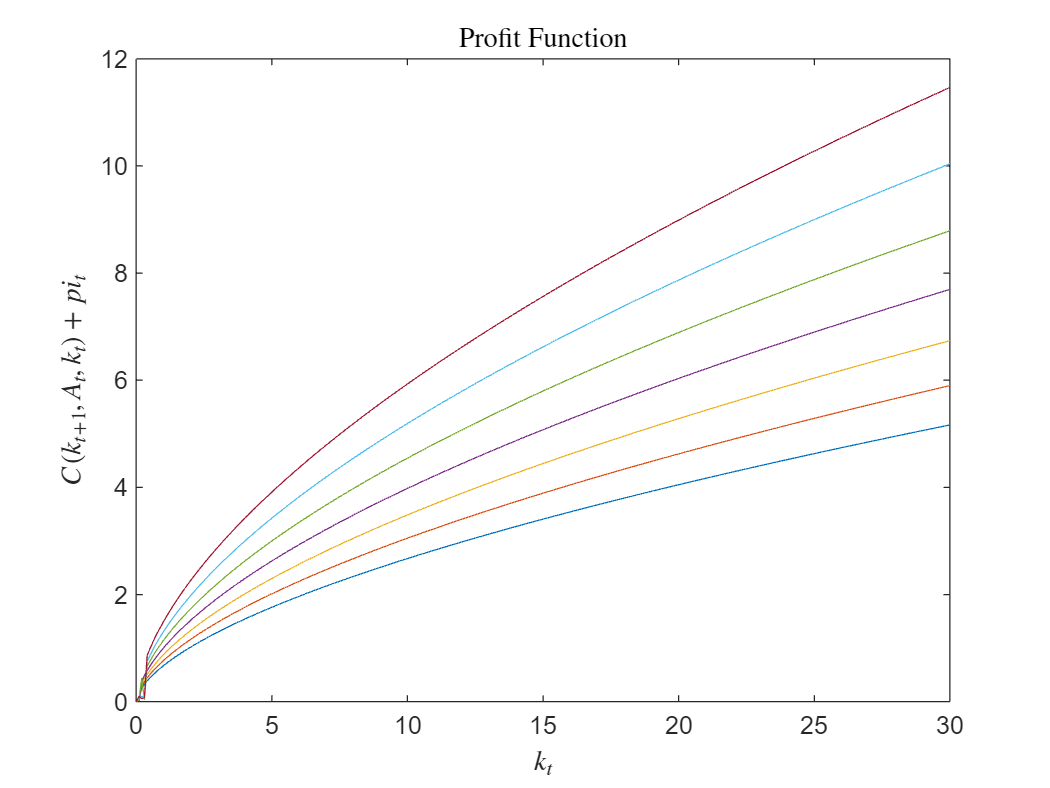

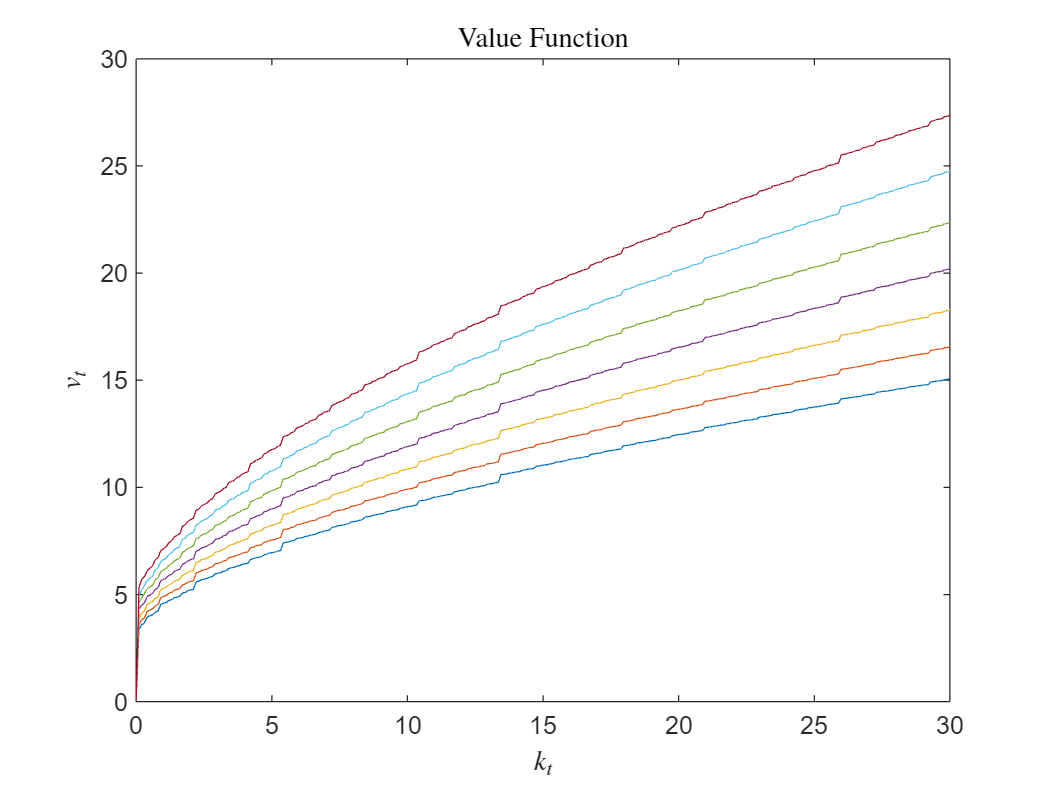

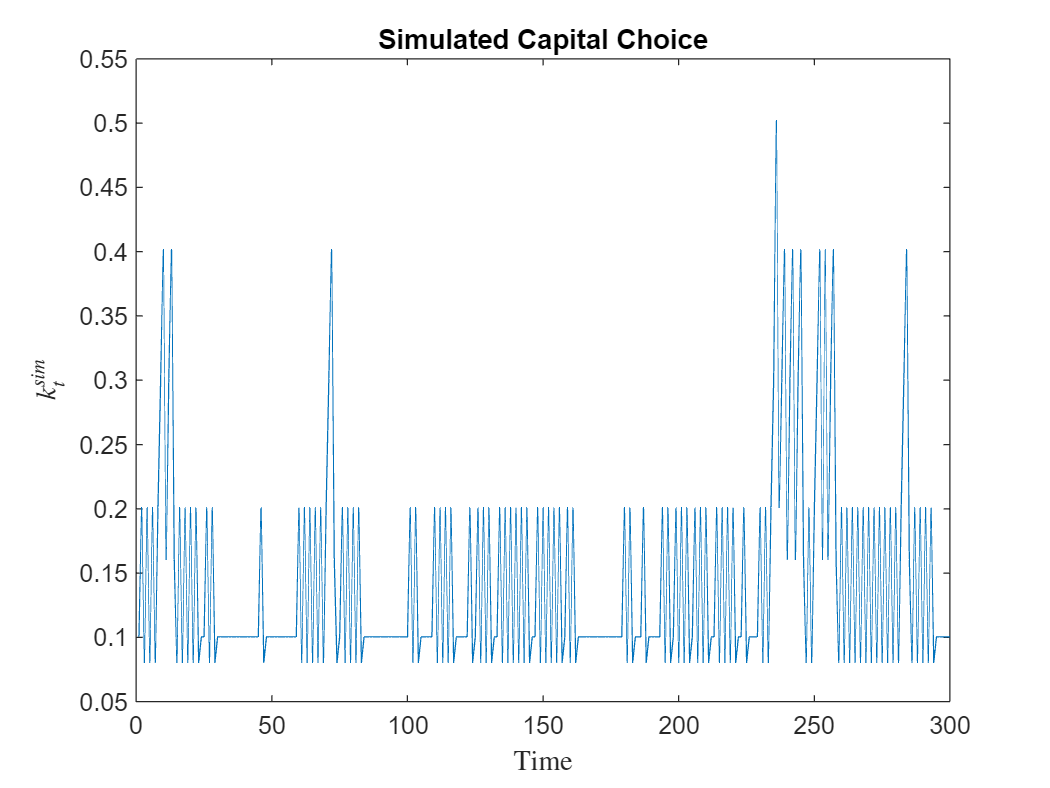

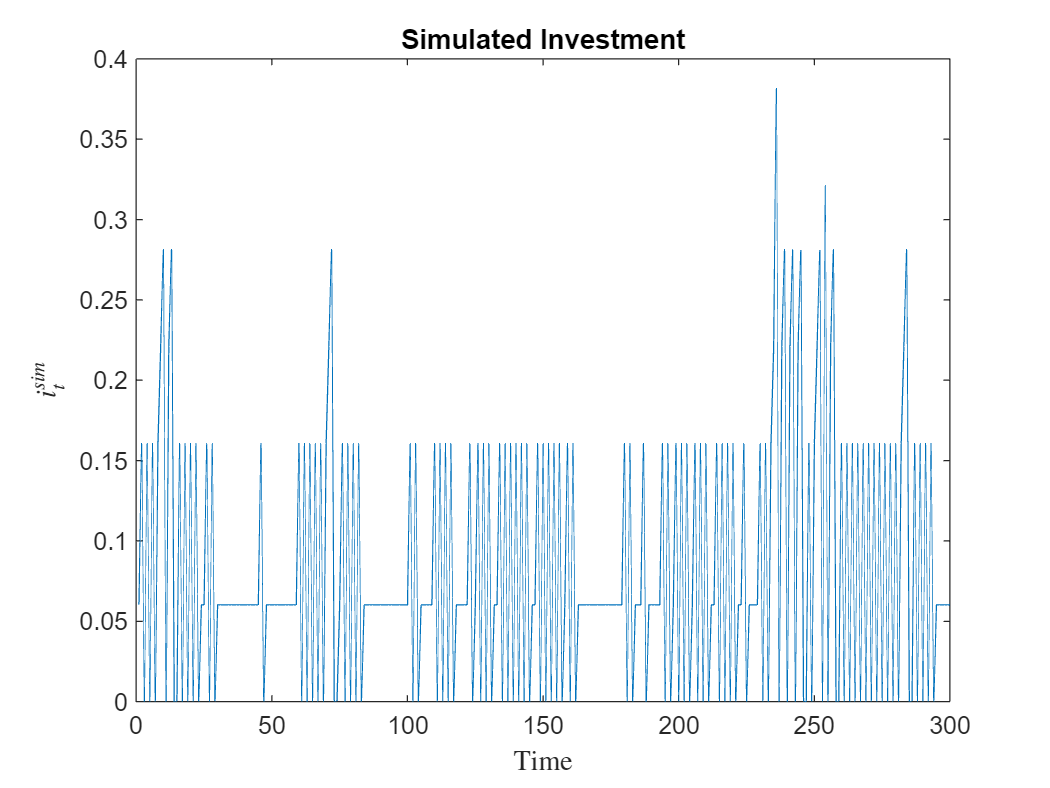

sim3 = simulate3.firm_dynamics(par,sol3); % Simulate the model.
my_graph3.plot_policy(par,sol3,sim3) % Plot the model functions and time series.

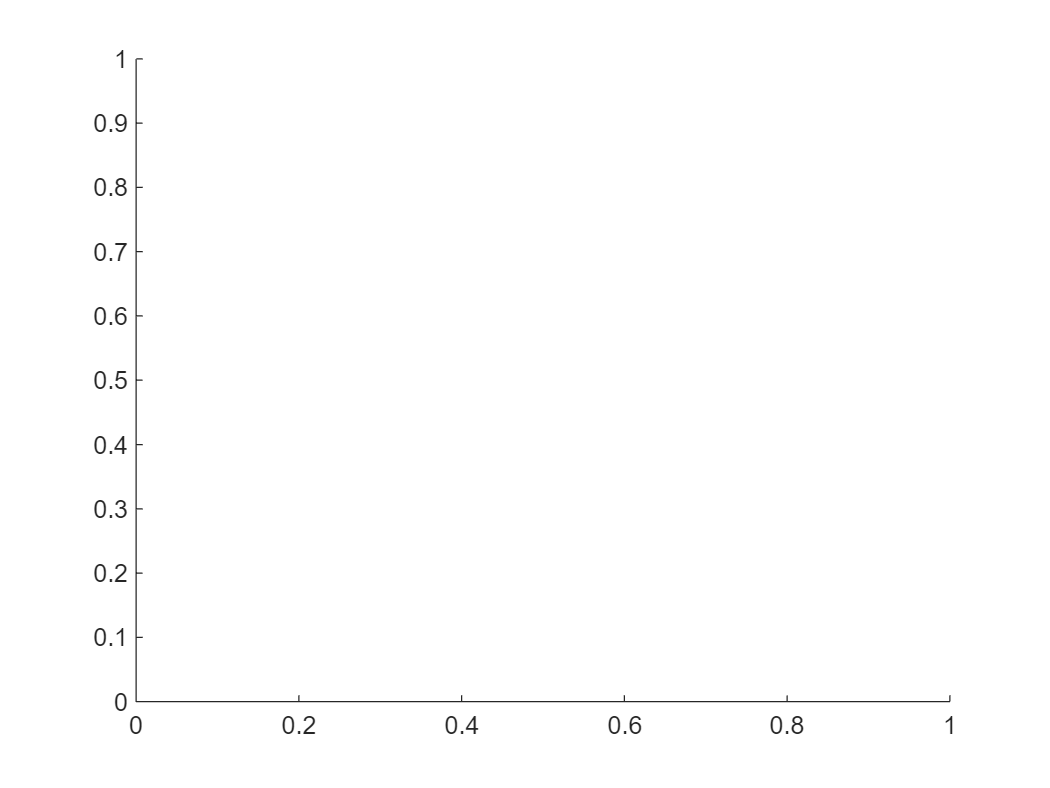

% Extract grids and simulated variables
Agrid = par.Agrid;
kgrid = par.kgrid;
A_sim = sim3.Asim;
k_sim = sim3.ksim;
invest_sim = sol3.invest_decision;

% Create figure
figure;
hold on;


% Logical indexing
invest_yes = invest_sim == 1;
invest_no = invest_sim == 0;

% Plot green for invest
scatter(A_sim(invest_yes), k_sim(invest_yes), 40, 'g', 'filled');

The logical indices contain a true value outside of the array bounds.


% Plot red for no invest
scatter(A_sim(invest_no), k_sim(invest_no), 40, 'r', 'filled');

xlabel('$A_t$ (Productivity)', 'Interpreter', 'latex');
ylabel('$k_t$ (Capital)', 'Interpreter', 'latex');
title('Discrete Investment Decisions over Time', 'Interpreter', 'latex');
legend({'Invest', 'No Invest'}, 'Location', 'best');
grid on;